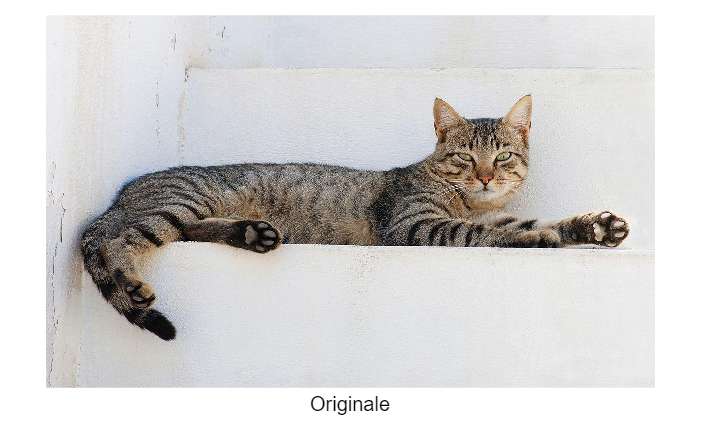

fullFileName = matlab.desktop.editor.getActiveFilename;
folderPath = fileparts(fullFileName);
folderPath = strrep(folderPath, 'MatLab', '');
folderPath = fullfile(folderPath, 'Python/dataset');
folderPath = fullfile(folderPath, 'original');
nome_img = 'Cat_August_2010-4.jpg';
folderPath = fullfile(folderPath, nome_img);

img = imread(folderPath);

imshow(img)
text(size(img,2)/2, size(img,1) + 10, 'Originale', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

Applicazione del rumore Striping Lines Noise

[rows, cols, channels] = size(img);

% Genera rumore uniforme [0,1]
stripe_noise = repmat(rand(1, cols), rows, 1);

% Porta il rumore a zero mean: sottrai la media
stripe_noise = stripe_noise - mean(stripe_noise(:));

% Scegli intensità del rumore (es. 30)
noise_strength = 25;

% Scala il rumore con intensità
stripe_noise = stripe_noise * noise_strength;

% Se RGB, espandi ai 3 canali
if channels == 3
    stripe_noise = repmat(stripe_noise, [1, 1, 3]);
end

% Somma il rumore all'immagine (converti a double prima)
noisy_img = double(img) + stripe_noise;

% Clipping per rientrare tra 0 e 255
noisy_img = uint8(min(max(noisy_img, 0), 255));

Mostra immagine con Rumore

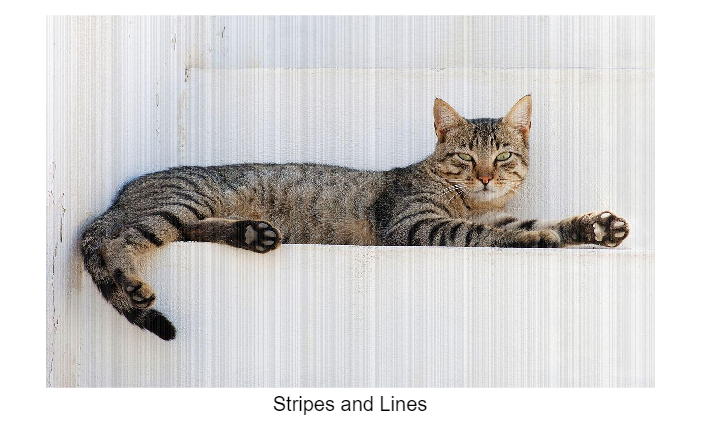

imshow(noisy_img)
text(size(noisy_img,2)/2, size(noisy_img,1) + 10, 'Stripes and Lines', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

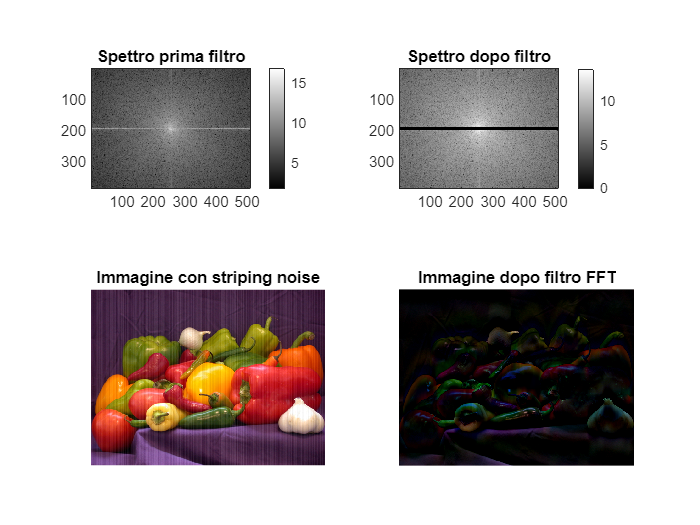

% Carica immagine di esempio
img = imread('peppers.png'); 
[rows, cols, channels] = size(img);

% Genera striping noise
stripe_noise = repmat(rand(1, cols), rows, 1);
stripe_noise = stripe_noise - mean(stripe_noise(:));
noise_strength = 25;
stripe_noise = stripe_noise * noise_strength;

if channels == 3
    stripe_noise = repmat(stripe_noise, [1, 1, 3]);
end

noisy_img = double(img) + stripe_noise;
noisy_img = uint8(min(max(noisy_img, 0), 255));

img_double = double(noisy_img);

% FFT 2D e filtro per ogni canale
img_fft = zeros(size(img_double));
for c = 1:channels
    F = fft2(img_double(:,:,c));
    
    % Spostiamo componente zero frequenza al centro per visualizzazione
    F_shift = fftshift(F);
    
    % Visualizza spettro prima filtro (solo per il primo canale RGB o grayscale)
    if c == 1
        figure;
        subplot(2,2,1);
        imagesc(log(abs(F_shift)+1)); colormap gray;
        title('Spettro prima filtro');
        axis image; colorbar;
    end
    
    % Crea maschera per attenuare basse frequenze verticali
    mask = ones(size(F));
    N = 5;
    mask(1:N, :) = 0;
    mask(end-N+1:end, :) = 0;
    
    F_filtered = F .* mask;
    F_filtered_shift = fftshift(F_filtered);
    
    % Visualizza spettro dopo filtro
    if c == 1
        subplot(2,2,2);
        imagesc(log(abs(F_filtered_shift)+1)); colormap gray;
        title('Spettro dopo filtro');
        axis image; colorbar;
    end
    
    img_fft(:,:,c) = real(ifft2(F_filtered));
end

img_fft = uint8(min(max(img_fft, 0), 255));

% Visualizza immagini nel dominio spaziale (immagini)
subplot(2,2,3); imshow(noisy_img); title('Immagine con striping noise');
subplot(2,2,4); imshow(img_fft); title('Immagine dopo filtro FFT');